clear, close all, clc

En strøm måles med to forskellige glastyper og tre forskellige fosfortyper.

load('dataset_problem_14_1.mat')

n = 3

n = 3

Opgave a)

Hvad er den interessante hypotse i denne test?

Der ønskes som sædvanligt at teste tre hypoteser:

B har ingen effekt, A har ingen effekt, og der er ingen interaktion.

Opgave b)

Lav en ANOVA-test med alpha = 0.01 og konkluder.

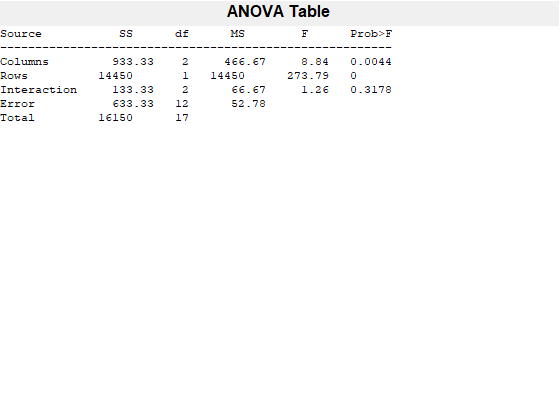

% Data skal omstruktureres, så det passer til
% ANOVA-funktionen
M = data(:,3:5);
M = M';
M = [M(:,1:3);M(:,4:6)];

P = anova2(M,n);

P1 = P(1)

P1 = 0.0044

P2 = P(2)

P2 = 1.2592e-09

P3 = P(3)

P3 = 0.3178


% Idet de to første er lave, forkastes både hypotese
% 1 og 2, altså at B og A ingen effekt har,
% men det kan ikke konkluderes, at der er nogen
% interaktion.

Opgave c)

Analyser residualerne fra eksperimentet.

[R VR CM] = ANOVA2Residuals(M,n)

R =    -5.0000   -1.6667    1.6667
    5.0000    8.3333   -3.3333
         0   -6.6667    1.6667
   -5.0000   15.0000   -5.0000
         0   -5.0000         0
    5.0000  -10.0000    5.0000


VR =    -5.0000   -1.6667    1.6667    5.0000    8.3333   -3.3333         0   -6.6667    1.6667   -5.0000   15.0000   -5.0000         0   -5.0000         0    5.0000  -10.0000    5.0000


CM =   285.0000  301.6667  288.3333
  235.0000  245.0000  225.0000


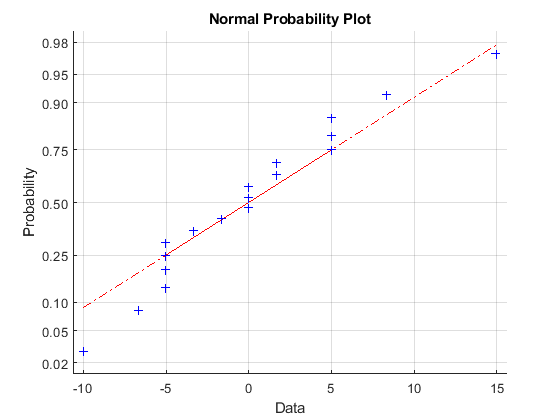

figure(4)
normplot(VR)